# Adds a CV Pipe in a network.

## This example contains: 

- Load a network. 

- Plot network components. 

- Get from and to nodes for add cv pipe. 

- Plot new network with changes. 

- Unload library.

## Clear - Start Toolkit 

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


## Load a network.

d = epanet('Net1.inp');

EPANET version {20200} loaded (EMT version {v2.2.1}).
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.



disp('Add a CV pipe')

Add a CV pipe


## Plot network components.

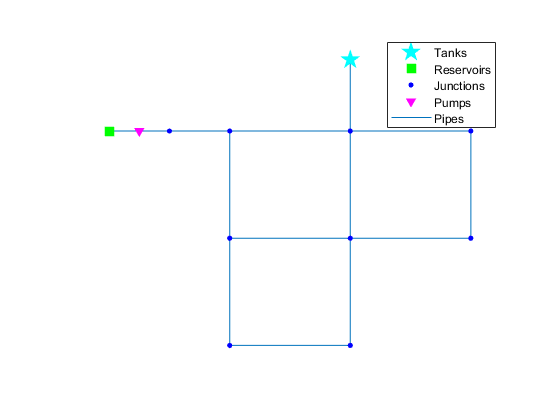

d.plot;

## Get from and to nodes for add cv pipe.

fromNode = d.getNodeNameID{2};
toNode = d.getNodeNameID{6};
node_index = d.addLinkPipeCV('CVPipe',fromNode,toNode);

## Plot new network with changes.

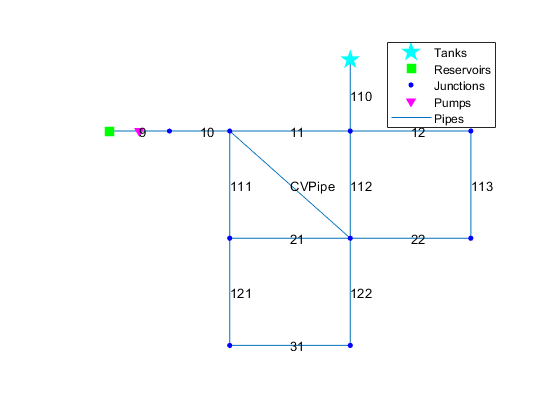

d.plot('links','yes');

## Unload library.

d.unload

EPANET Class is unloaded
